# EDA example with PCA using the MEDA Toolbox.

**MEDA Version:** v1.6

**Coded by:** José Camacho (josecamacho@ugr.es) and Jesús García (gsus@ugr.es)

**Last modification:** 23/Jan/2025

## Description 

The data represent network traffic collected through a practical lesson of the Network Management course of the Telecommunication Engieneering degree at the University of Granada. During this session, the students were dealing with the configuration of polling and traps generation with the Simple Network Management Protocol (SNMP), in the Cisco routers and switches of the laboratory.

See README.txt for more details.

 Data set and Analysis: 

   J. Camacho, P. Padilla and J. Verdejo, Networkmetrics: Multivariate 

      Visual Analytics for Time Series Networking Data. Technical Report. 

% 	Variables:
%
%   1	A.ifIn1		18 	B.ifIn9		35	C.ifIn9
% 	2	A.ifIn2		19 	B.ifIn10	36	C.ifIn10
% 	3	A.ifIn8		20 	B.ifIn4		37	C.ifIn12
% 	4	A.ifIn14	21 	B.ifOut1	38	C.ifIn14
% 	5	A.ifOut1	22 	B.ifOut2	39	C.ifOut1
% 	6	A.ifOut2	23 	B.ifOut3	40	C.ifOut2
% 	7	A.ifOut3	24 	B.ifOut4	41	C.ifOut3
% 	8	A.ifOut4	25 	B.ifOut8	42	C.ifOut4
% 	9	A.ifOut8	26 	B.ifOut9	43	C.ifOut5
% 	10	A.ifOut9	27 	B.ifOut10	44	C.ifOut7
% 	11	A.ifOut10	28 	B.ifOut11	45	C.ifOut9
% 	12	A.ifOut11	29 	B.ifOut12	46	C.ifOut10
% 	13	A.ifOut12	30 	B.ifOut14	47	C.ifOut11
% 	14	A.ifOut14	31	C.ifIn1		48	C.ifOut12
% 	15	B.ifIn1		32	C.ifIn2		49	C.ifOut14
% 	16	B.ifIn2		33	C.ifIn3		
% 	17	B.ifIn8		34	C.ifIn5		
%     
% where the name of each variable follows the format <switch>.if[In|Out]<N>. 
% The remaining ports of the switches did not present any traffic load.

## Inicialization, remember to set the path of the toolbox

prep_x = 1; % centre X
max_PCs = 10; % maximum number of PCs to take into account

load data_proc

## Step 1: Selection of the LVs

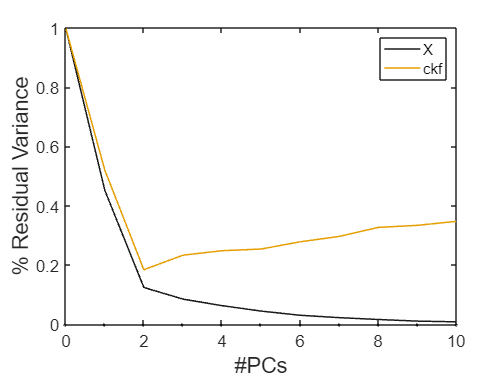

varPca(cal,'Pcs',1:max_PCs,'Preprocessing',prep_x, 'PlotCkf', true); % 2 PCs seem to be adequate

## Step 2: observations distribution and relationships

Scores and residuals, outliers detection

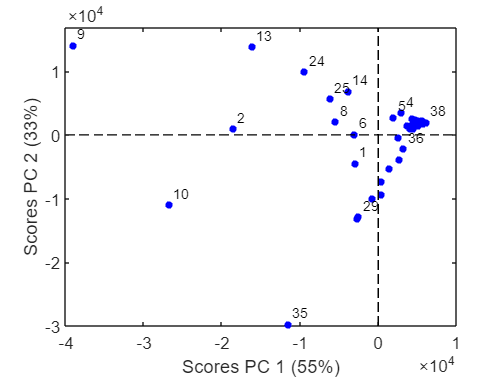

scoresPca(cal,'Pcs',1:2,'Preprocessing',prep_x); 

There are two directions of variability, and observations 2, 9, 10 and 35 should be studied with more detail

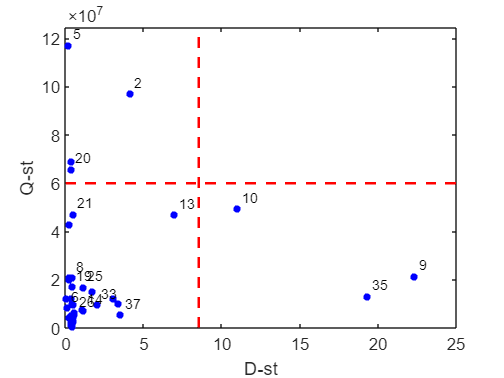

mspcPca(cal,'Pcs',1:2,'Preprocessing',prep_x); 

check also 5 (residuals)

## Step 3: variables distribution and relationships

Loadings, MEDA and residuals, selection of variables

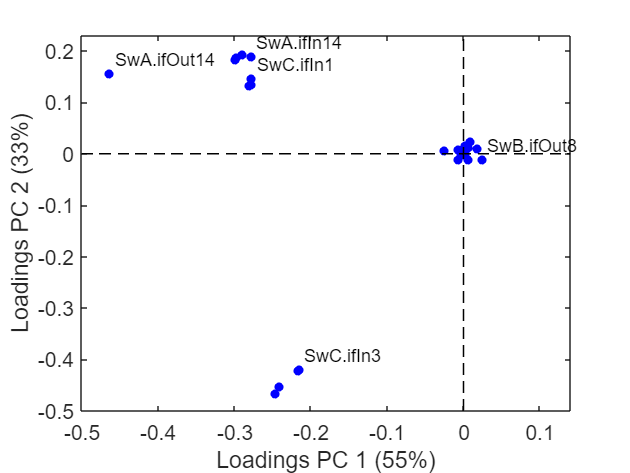

loadingsPca(cal,'Pcs',1:2,'Preprocessing',prep_x,'VarsLabel',lab);

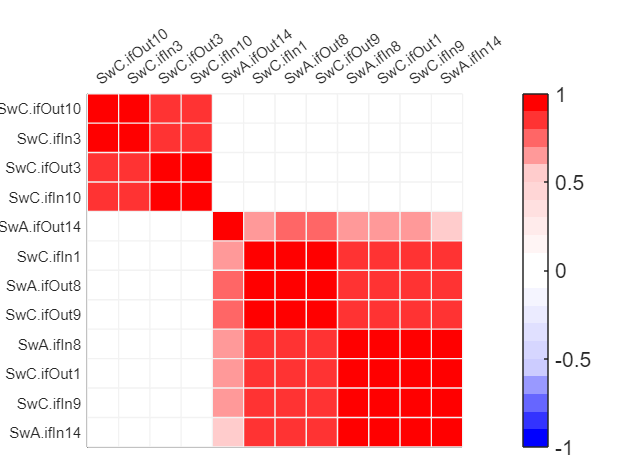

% two groups of variables are detected 
% GR1: C.ifIn10, C.ifOut10, C.ifIn3, C.ifOut3: traffic between Px/2 <=> Rx-A
% GR2: C.ifOut9, A.ifOut8, C.ifIn1, C.ifIn9, A.ifIn8, C.ifOut1, A.ifIn14, 
%    A.ifOut14:  traffic between Px/1 <=> SWx-A

medaPca(cal,'Pcs',1:2,'Preprocessing',prep_x,'Threshold',0.5,'Seriated',true,'Discard',true,'VarsLabel',lab);

The same two groups are found

## Steps 1-3 can be repeated for a subset of selected variables

To do that, excute the following code and then repeat the steps 1-3. Basically, the same conclusions are found, but this selection is suggested to simplify the interpretation of Step 4.

load data_proc
sel = [3 4 9 14 31 33 35 36 39 41 45 46];

map = medaPca(cal,'Pcs',1:2,'Preprocessing',prep_x,'Threshold',0.5,'Seriated',false, 'Discard', true);
close gcf;

[map,ord] = seriation(map); % variables reordering
cal = cal(:,sel(ord));
test = test(:,sel(ord));
lab = lab(sel(ord));

## Step 4: investigate differences between observations

Apply oMEDA of the two trends found in the score plot line plots are used to confirm the result

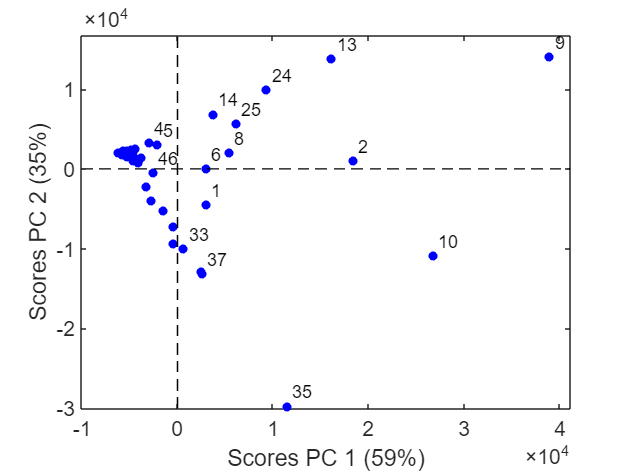

scoresPca(cal,'Pcs',1:2,'Preprocessing',prep_x);

The first trend is related to the group of variables GR1

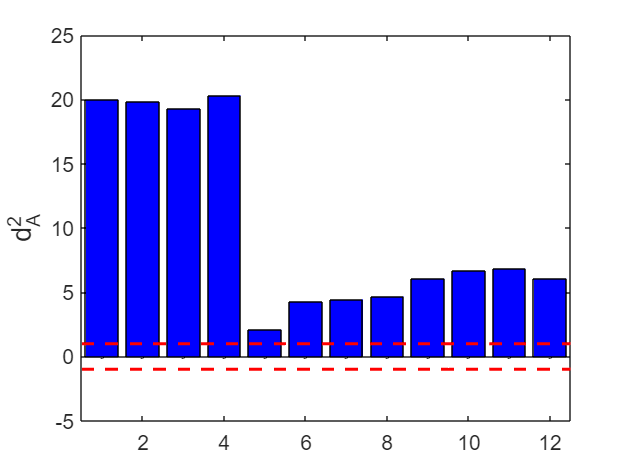

dummy=-ones(48,1);
dummy(35)=2;
dummy([37,29,33,45])=1;
dummy([10,2,6,8,1,25,14,24,13,9])=0;
omedaPca(cal,1:2,cal,dummy,'Preprocessing',prep_x,'ControlLim',1,'Normalize',1,'VarsLabel',lab);

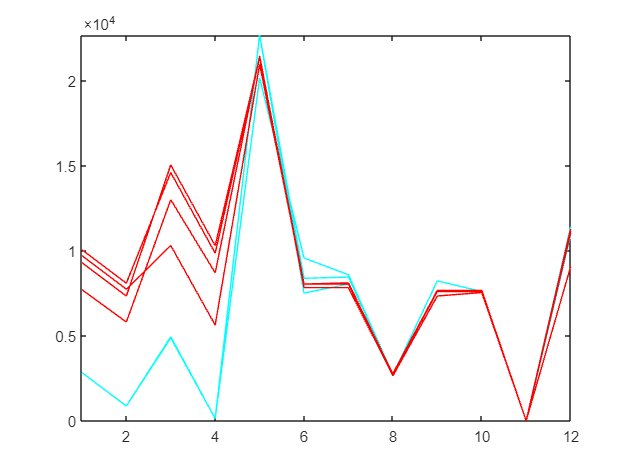

figure, plot(1:size(cal,2),cal([12 16 19 18],:)','c'), hold on, plot(1:size(cal,2),cal([37,29,33,45],:)','r'), axis tight

The second trend is mainly related to the group of variables GR2

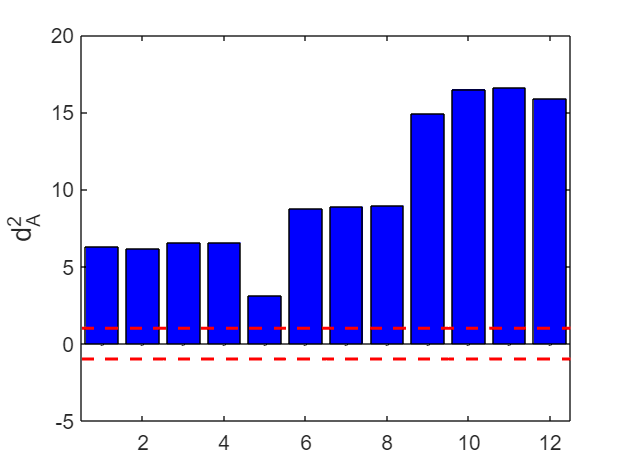

dummy=-ones(48,1);
dummy(9)=2;
dummy([13,24,14,25])=1;
dummy([10,2,9,6,8,1,26,28,36,22,23,29,35,37,45])=0;
omedaPca(cal,1:2,cal,dummy,'Preprocessing',prep_x,'ControlLim',1,'Normalize',1,'VarsLabel',lab);

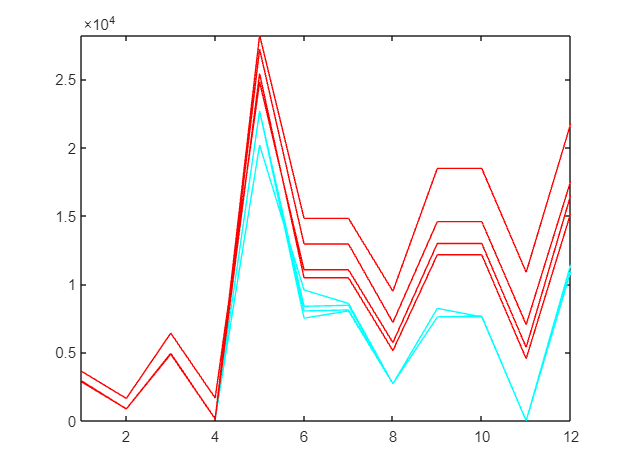

figure, plot(1:size(cal,2),cal([12 16 19 18],:)','c'), hold on, plot(1:size(cal,2),cal([13,24,14,25],:)','r'), axis tight

## Step 4b: investigate differences with outliers

oMEDA and line plots of outliers. Basically, all outliers present high load of traffic.

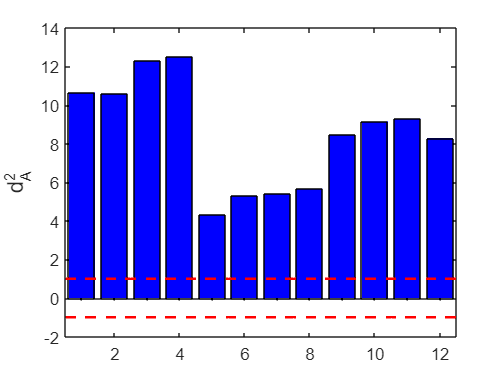

% outlier 2
dummy=-ones(48,1);
dummy([10,2,6,8,1,25,14,24,13,9,26,28,36,29,35,37,33,45])=0;
dummy(2)=1;
omedaPca(cal,1:2,cal,dummy,'Preprocessing',prep_x,'ControlLim',1,'Normalize',1,'VarsLabel',lab);

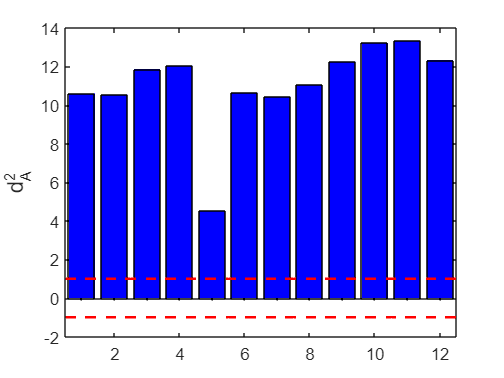

% outlier 9
dummy=-ones(48,1);
dummy([10,2,6,8,1,25,14,24,13,9,26,28,36,29,35,37,33,45])=0;
dummy(9)=1;
omedaPca(cal,1:2,cal,dummy,'Preprocessing',prep_x,'ControlLim',1,'Normalize',1,'VarsLabel',lab);

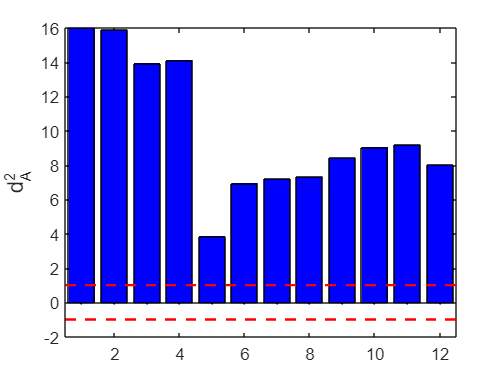

% outlier 10
dummy=-ones(48,1);
dummy([10,2,6,8,1,25,14,24,13,9,26,28,36,29,35,37,33,45])=0;
dummy(10)=1;
omedaPca(cal,1:2,cal,dummy,'Preprocessing',prep_x,'ControlLim',1,'Normalize',1,'VarsLabel',lab);

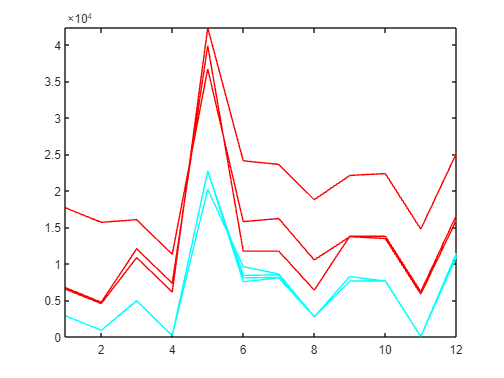

% line plot to confirm results
figure, plot(1:size(cal,2),cal([12 16 19 18],:)','c'), hold on, plot(1:size(cal,2),cal([2,9,10],:)','r'), axis tight

## Step 5: data set de test

Score plot and oMEDA (perform with the complete set of variables).

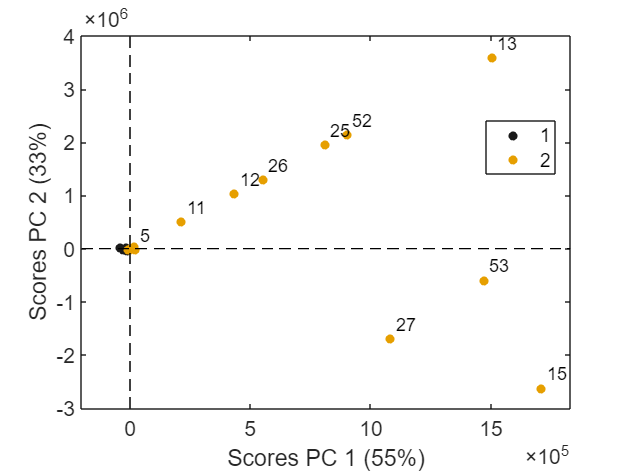

load data_proc

scoresPca(cal,'Pcs',1:2,'ObsTest', test,'Preprocessing',prep_x);

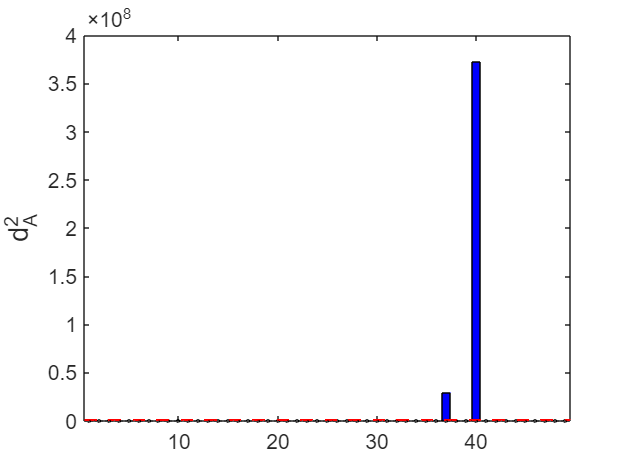

dummy=-ones(101,1);
dummy([61,100,73,74,60,59])=1;
dummy([63,75,101])=0;
omedaPca(cal,1:2,[cal;test],dummy,'Preprocessing',prep_x,'ControlLim',1,'Normalize',1,'VarsLabel',lab);

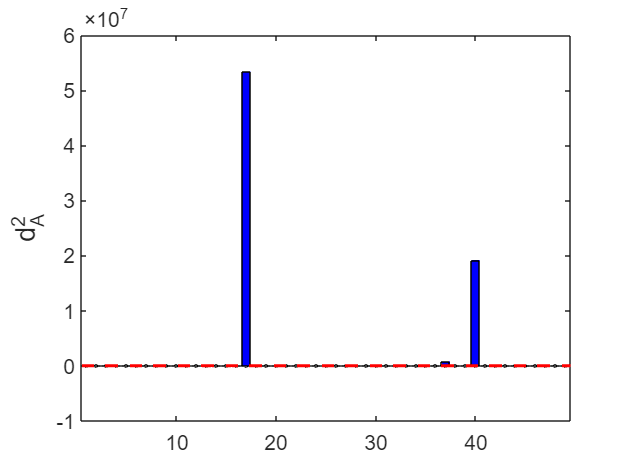

dummy=-ones(101,1);
dummy([61,100,73,74,60,59])=0;
dummy([63,75,101])=1;
omedaPca(cal,1:2,[cal;test],dummy,'Preprocessing',prep_x,'ControlLim',1,'Normalize',1,'VarsLabel',lab);

## Copyright (C) 2025  University of Granada, Granada

This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program.  If not, see <http://www.gnu.org/licenses/>.